## Análisis cinemático

clear
clc


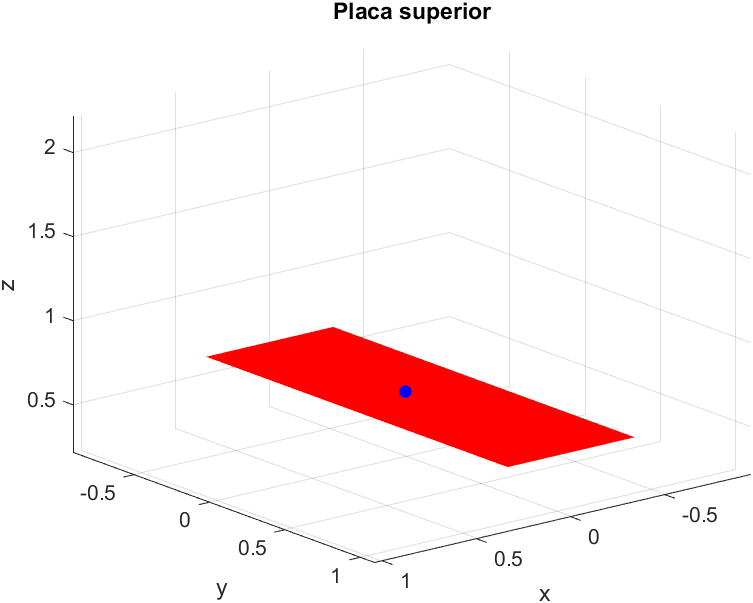

b=2.3;
h=0.675;

syms beta(t) theta(t) x y z Xa(t) Za(t)
Pi=[x y z];



### Ecuaciones generales


Wbeta(t)=[beta(t) 0 0];
Wtheta(t)=[0 theta(t) 0];
Wtotal(t)=diff(Wbeta(t)+Wtheta(t));

VelocidadPO(t)=cross(Wtotal(t),Pi);
aceleracionAngular(t)=diff(Wtotal(t));

AceleracionPO(t)=cross(aceleracionAngular(t),Pi)+cross(Wtotal(t),VelocidadPO(t));


Velocidad=formula(VelocidadPO(t)+diff([Xa(t) 0 Za(t)]));
Vx=Velocidad(1)

$$Vx = z\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}\mathrm{Xa}\left(t\right)$$

Vy=Velocidad(2)

$$Vy = -z\,\frac{\partial }{\partial t}\beta \left(t\right)$$

Vz=Velocidad(3)

$$Vz = y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}\mathrm{Za}\left(t\right)$$


Aceleracion=formula(AceleracionPO(t)+diff(diff([Xa(t) 0 Za(t)])));
Ax=Aceleracion(1)

$$Ax = z\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\left(y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\mathrm{Xa}\left(t\right)$$

Ay=Aceleracion(2)

$$Ay = -\left(y\,\frac{\partial }{\partial t}\beta \left(t\right)-x\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-z\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)$$

Az=Aceleracion(3)

$$Az = y\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-z\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}-z\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-x\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\mathrm{Za}\left(t\right)$$

### Cinemática Avance (actuador Xa)

syms  vmaxXa tfXa 
assume (tfXa>0);

g=9.81;
acXa=0.5*g;
x=0.3;

f1=acXa==2*vmaxXa/tfXa;
f2=x==vmaxXa.*tfXa/2;

[vmaxXa,tfXa]=solve([f1 f2],[vmaxXa tfXa])

$$vmaxXa = \frac{3\,\sqrt{1635}}{100}$$

$$tfXa = \frac{4\,\sqrt{1635}}{327}$$


Xa(t)=piecewise(t<0.5*tfXa,0.5*acXa*t^2,t>=0.5*tfXa,vmaxXa*t-0.5*acXa*(t-0.5*tfXa)^2-vmaxXa*tfXa/4)

$$Xa(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{400} & \text{ if }t<\frac{2\,\sqrt{1635}}{327}\\ \frac{3\,\sqrt{1635}\,t}{100}-\frac{981\,{\left(t-\frac{2\,\sqrt{1635}}{327}\right)}^{2}}{400}-\frac{3}{20} & \text{ if }\frac{2\,\sqrt{1635}}{327}\leq t \end{array}\right.$$

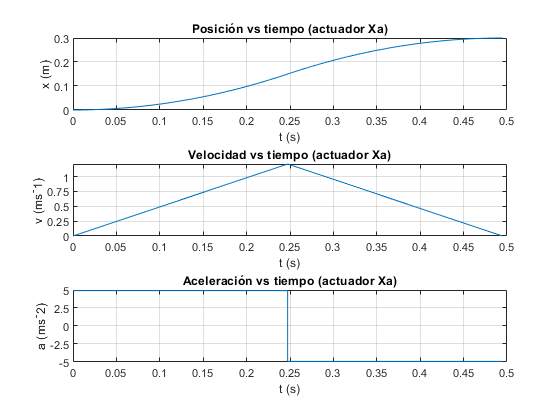

figure()
subplot(3,1,1)
fplot(Xa,[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('x (m)')
yticks(0:0.1:0.3)
title('Posición vs tiempo (actuador Xa)')
subplot(3,1,2)
fplot(diff(Xa),[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
yticks(0:0.25:1.25)
title('Velocidad vs tiempo (actuador Xa)')
subplot(3,1,3)
fplot(diff(diff(Xa)),[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
yticks(-7.5:2.5:7.5)
title('Aceleración vs tiempo (actuador Xa)')

### Cinemática Arfada (actuador Za)

syms  vmaxZa tfZa 
assume (tfZa>0);

g=9.81;
acXa=0.5*g;
x=0.2;
f1=acXa==2*vmaxZa/tfZa;
f2=x==vmaxZa.*tfZa/2;

[vmaxZa,tfZa]=solve([f1 f2],[vmaxZa tfZa])

$$vmaxZa = \frac{3\,\sqrt{1090}}{100}$$

$$tfZa = \frac{4\,\sqrt{1090}}{327}$$


Za(t)=piecewise(t<0.5*tfZa,0.5*acXa*t^2,t>=0.5*tfZa,vmaxZa*t-0.5*acXa*(t-0.5*tfZa)^2-vmaxZa*tfZa/4)

$$Za(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{400} & \text{ if }t<\frac{2\,\sqrt{1090}}{327}\\ \frac{3\,\sqrt{1090}\,t}{100}-\frac{981\,{\left(t-\frac{2\,\sqrt{1090}}{327}\right)}^{2}}{400}-\frac{1}{10} & \text{ if }\frac{2\,\sqrt{1090}}{327}\leq t \end{array}\right.$$

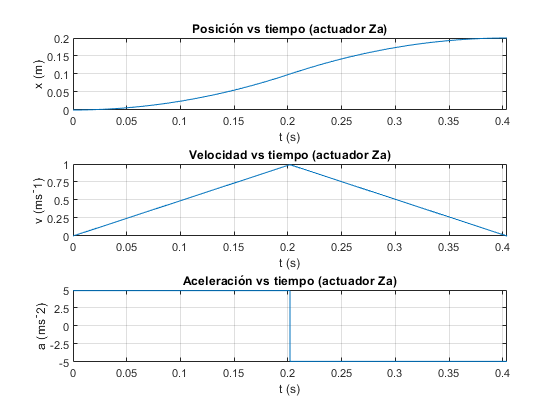

figure()
subplot(3,1,1)
fplot(Za,[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('x (m)')
yticks(0:0.05:0.2)
title('Posición vs tiempo (actuador Za)')
subplot(3,1,2)
fplot(diff(Za),[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
yticks(0:0.25:1)
title('Velocidad vs tiempo (actuador Za)')
subplot(3,1,3)
fplot(diff(diff(Za)),[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
yticks(-7.5:2.5:7.5)
title('Aceleración vs tiempo (actuador Za)')